% - - - - - - - - BINARY U-N and U-O PHASE STABILITY PLOTS - - - - - - - - 


%  - - - - UN - - - - - - -
tic
% importing data - - - - - - - - -
training_data = readtable("targets_extra-cols.csv"); % data used to train the models
nn_data = readtable("data_binaryUN-NN.csv");         % Neural Network Predictions 
rf_data = readtable("data_binaryUN-RF.csv");         % Random Forrest Predictions
nnrf_data = readtable("data_binaryUN-NNRF.csv");     % Ensemble model Predictions (NN & RF)

% paring down training data to points relevent to UN only - - - - - -- 
un_training = table();
j = 1;
for i = 1:height(training_data)
    str = regexprep(char(training_data{i,"formula"}), '\d', ''); 
    if strcmp(str,'UN') % if we remove numbers (as done above) all UxNy will be displayed as "UN"
        un_training(j,:) = training_data(i,:);
        j = j+1;
    end
end
clear training_data
toc

Elapsed time is 1.827903 seconds.


tic
% calculation nitrogen fraction from chem formula - - - - - - - - 
train_nfrac = zeros(height(un_training),1);
for i = 1:height(un_training)
    train_nfrac(i) = oxidant_fraction(un_training{i,2},'N');
end
nn_nfrac = zeros(height(nn_data),1);
for i = 1:height(nn_data)
    nn_nfrac(i) = oxidant_fraction(nn_data{i,2},'N');
end
rf_nfrac = zeros(height(rf_data),1);
for i = 1:height(rf_data)
    rf_nfrac(i) = oxidant_fraction(rf_data{i,2},'N');
end
nnrf_nfrac = zeros(height(nnrf_data),1);
for i = 1:height(nnrf_data)
    nnrf_nfrac(i) = oxidant_fraction(nnrf_data{i,2},'N');
end


% reformatting tables to aid plotting - - - - - - - -
pure_U_entry = table(0,0,VariableNames={'oxidant_fraction','Ef_eV'}, RowNames={'U'});
pure_N_entry = table(1,0,VariableNames={'oxidant_fraction','Ef_eV'}, RowNames={'N'});
train_post = table(train_nfrac,un_training{:,"Ef"},... % UxNy Training data
             VariableNames={'oxidant_fraction','Ef_eV'},...
             RowNames=un_training{:,"formula"});
train_post = vertcat(train_post,pure_N_entry,pure_U_entry);
train_post = sortrows(train_post,"oxidant_fraction","ascend");
nn_post = table(nn_nfrac,nn_data{:,"Ef"},... % Neural Network data post processing (and ready for plotting)
          VariableNames={'oxidant_fraction','Ef_eV'},...
          RowNames=nn_data{:,"formula"});
nn_post = vertcat(nn_post,pure_N_entry,pure_U_entry);
nn_post = sortrows(nn_post,"oxidant_fraction","ascend");

rf_post = table(rf_nfrac,rf_data{:,"Ef"},... % Neural Network data post processing (and ready for plotting)
          VariableNames={'oxidant_fraction','Ef_eV'},...
          RowNames=rf_data{:,"formula"});
rf_post = vertcat(rf_post,pure_N_entry,pure_U_entry);
rf_post = sortrows(rf_post,"oxidant_fraction","ascend");

nnrf_post = table(nnrf_nfrac,nnrf_data{:,"Ef"},... % Neural Network data post processing (and ready for plotting)
          VariableNames={'oxidant_fraction','Ef_eV'},...
          RowNames=nnrf_data{:,"formula"});
nnrf_post = vertcat(nnrf_post,pure_N_entry,pure_U_entry);
nnrf_post = sortrows(nnrf_post,"oxidant_fraction","ascend");
clear nn_data rf_data nnrf_data
toc

Elapsed time is 0.101334 seconds.


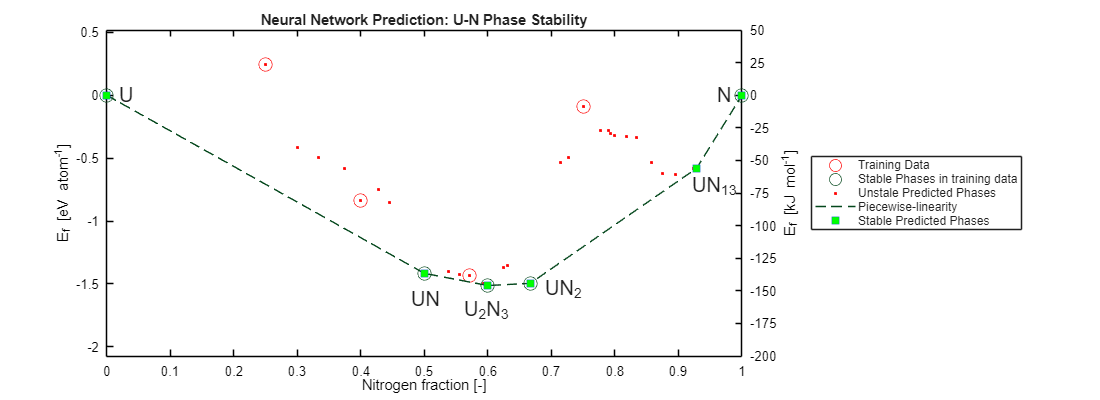

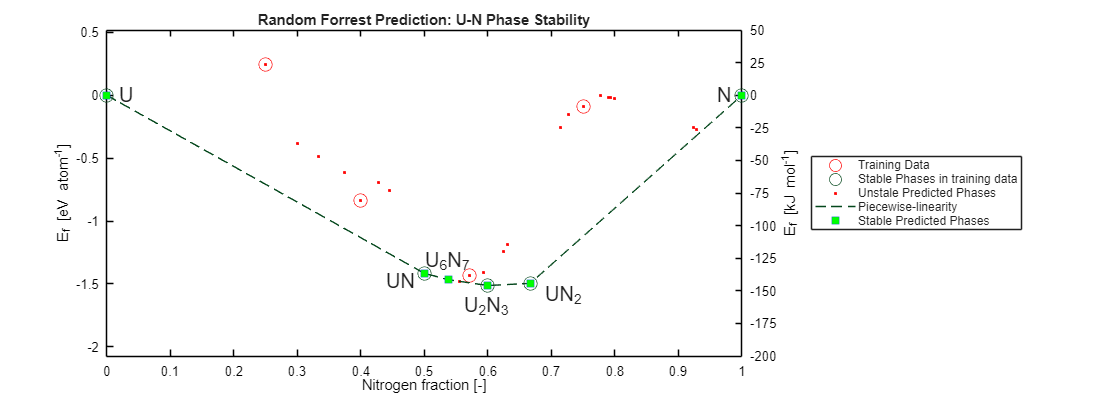

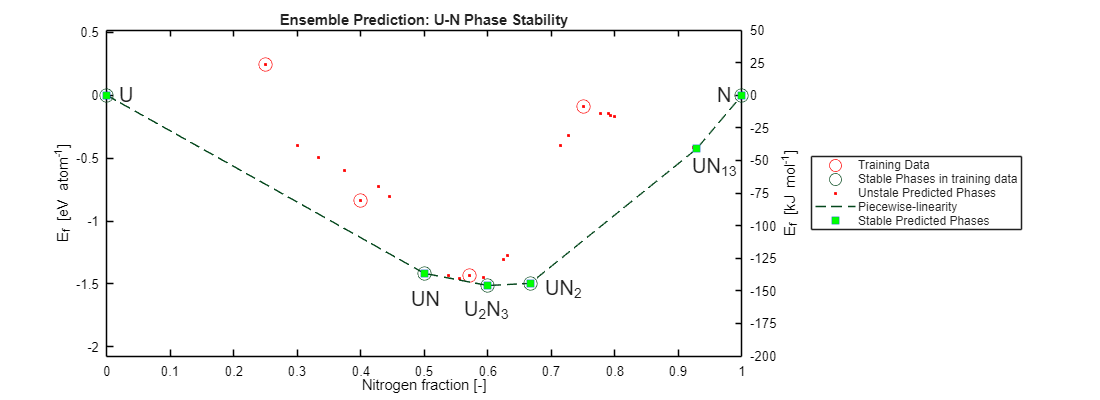

tic
for i = 1:1 % for loop to force plotting without line breaks
% Neural Network Plot - - - - -
stable_phase_plot(nn_post, train_post,'Neural Network','N',...
                  [0.02 , -0.021 , -0.04 , 0.02  , -0.01 , -0.04; 
                   0    , -0.2   , -0.2  , -0.05 , -0.15 , 0    ])
% Random Forrest Plot - - - - - - 
stable_phase_plot(rf_post, train_post, 'Random Forrest','N',...
                  [0.02 , -0.06 , -0.04 , -0.04 , 0.02 , -0.04; 
                   0    , -0.06 , 0.14  , -0.17 , -0.1    , 0    ])
% Ensemble Learning Plot - - - - - -
stable_phase_plot(nnrf_post, train_post, 'Ensemble','N',...
                  [0.02 , -0.021 , -0.04 , 0.02  , -0.01 , -0.04; 
                   0    , -0.2   , -0.2  , -0.05 , -0.15 , 0    ])
end

toc

Elapsed time is 6.486904 seconds.


% - - - - - - - UO - - - - - - - - - - 
% now we are doing the same but for a;; UxOy complexes

tic
% importing data - - - - - - - - -
training_data = readtable("targets_extra-cols.csv"); % data used to train the models
nn_data = readtable("data_binaryUO-NN.csv");         % Neural Network Predictions 
rf_data = readtable("data_binaryUO-RF.csv");         % Random Forrest Predictions
nnrf_data = readtable("data_binaryUO-NNRF.csv");     % Ensemble model Predictions (NN & RF)

% paring down training data to points relevent to UN only - - - - - -- 
uo_training = table();
j = 1;
for i = 1:height(training_data)
    str = regexprep(char(training_data{i,"formula"}), '\d', ''); 
    if strcmp(str,'UO') % if we remove numbers (as done above) all UxNy will be displayed as "UN"
        uo_training(j,:) = training_data(i,:);
        j = j+1;
    end
end
clear training_data
toc

Elapsed time is 2.058158 seconds.



tic
% calculation oxidant fraction from chem formula - - - - - - - - 
train_ofrac = zeros(height(uo_training),1);
for i = 1:height(uo_training)
    train_ofrac(i) = oxidant_fraction(uo_training{i,2},'O');
end
nn_ofrac = zeros(height(nn_data),1);
for i = 1:height(nn_data)
    nn_ofrac(i) = oxidant_fraction(nn_data{i,2},'O');
end
rf_ofrac = zeros(height(rf_data),1);
for i = 1:height(rf_data)
    rf_ofrac(i) = oxidant_fraction(rf_data{i,2},'O');
end
nnrf_ofrac = zeros(height(nnrf_data),1);
for i = 1:height(nnrf_data)
    nnrf_ofrac(i) = oxidant_fraction(nnrf_data{i,2},'O');
end


% reformatting tables to aid plotting - - - - - - - -
pure_U_entry = table(0,0,VariableNames={'oxidant_fraction','Ef_eV'}, RowNames={'U'});
pure_N_entry = table(1,0,VariableNames={'oxidant_fraction','Ef_eV'}, RowNames={'O'});
train_post = table(train_ofrac,uo_training{:,"Ef"},... % UxNy Training data
             VariableNames={'oxidant_fraction','Ef_eV'},...
             RowNames=uo_training{:,"formula"});
train_post = vertcat(train_post,pure_N_entry,pure_U_entry);
train_post = sortrows(train_post,"oxidant_fraction","ascend");
nn_post = table(nn_ofrac,nn_data{:,"Ef"},... % Neural Network data post processing (and ready for plotting)
          VariableNames={'oxidant_fraction','Ef_eV'},...
          RowNames=nn_data{:,"formula"});
nn_post = vertcat(nn_post,pure_N_entry,pure_U_entry);
nn_post = sortrows(nn_post,"oxidant_fraction","ascend");

rf_post = table(rf_ofrac,rf_data{:,"Ef"},... % Neural Network data post processing (and ready for plotting)
          VariableNames={'oxidant_fraction','Ef_eV'},...
          RowNames=rf_data{:,"formula"});
rf_post = vertcat(rf_post,pure_N_entry,pure_U_entry);
rf_post = sortrows(rf_post,"oxidant_fraction","ascend");

nnrf_post = table(nnrf_ofrac,nnrf_data{:,"Ef"},... % Neural Network data post processing (and ready for plotting)
          VariableNames={'oxidant_fraction','Ef_eV'},...
          RowNames=nnrf_data{:,"formula"});
nnrf_post = vertcat(nnrf_post,pure_N_entry,pure_U_entry);
nnrf_post = sortrows(nnrf_post,"oxidant_fraction","ascend");
clear nn_data rf_data nnrf_data
toc

Elapsed time is 0.104056 seconds.


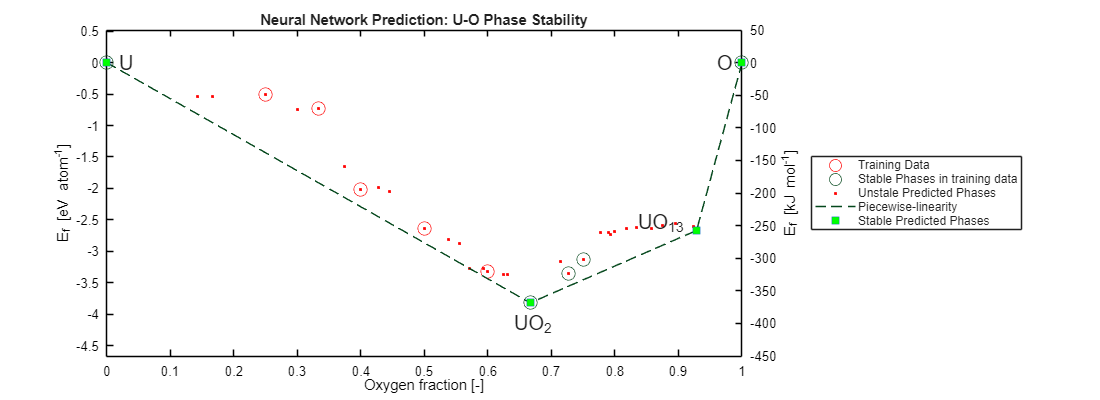

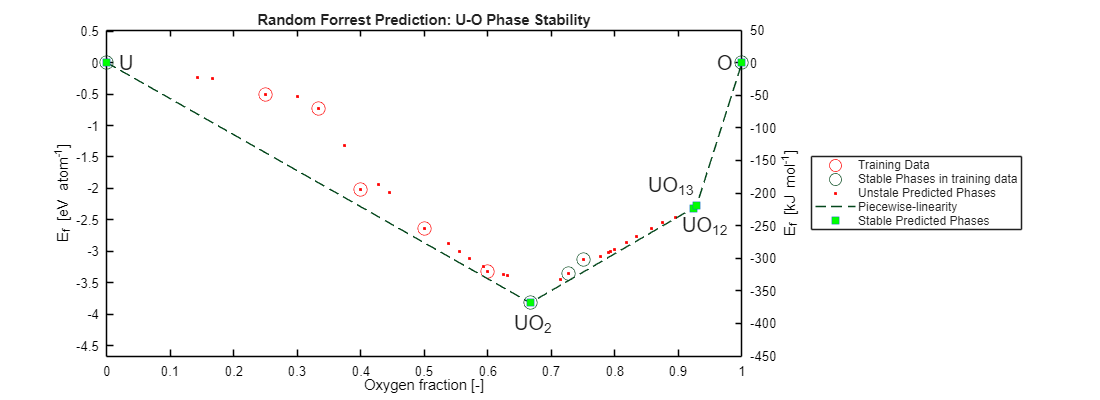

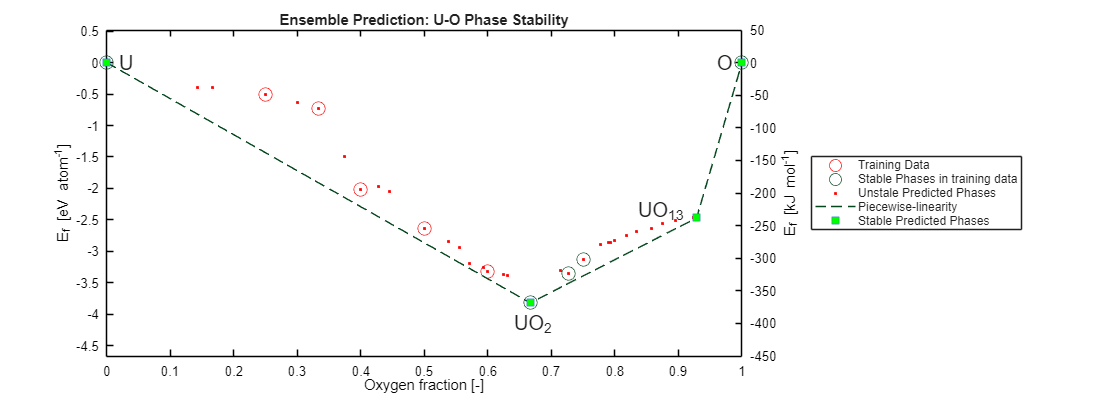

tic
for i = 1:1 % for loop to force plotting without line breaks
% Neural Network Plot - - - - -
stable_phase_plot(nn_post, train_post,'Neural Network','O',...
                  [0.02 , -0.028   , -0.095 , -0.04; 
                   0    , -0.35     , 0.1    , 0    ])
% Random Forrest Plot - - - - - - 
stable_phase_plot(rf_post, train_post, 'Random Forrest','O',...
                  [0.02 , -0.028 , -0.02 , -0.08 , -0.04; 
                   0    , -0.35   , -0.3  , 0.3   , 0    ])
% Ensemble Learning Plot - - - - - -
stable_phase_plot(nnrf_post, train_post, 'Ensemble','O',...
                  [0.02 , -0.028   , -0.095 , -0.04; 
                   0    , -0.35     , 0.1    , 0    ])
end

% Relevent functions to script - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -

function stable_phase_plot(T,training,learning_type,element,tff)
    % this script governs the plotting of our phase stability plots. simple
    % plotting of training data, all predicted phases, peicewise linearity
    % between phases and the stable phases themselves with text
    % discription. Note that the tff feild is required to move the text
    % such that it is clear on the graph, there is no automation to this.
    [y_pl, stable_phases, stable_phase_formula] = stable_phase_identification(T);
    [~, stable_training_phases, ~] = stable_phase_identification(training);
    x = T{:,"oxidant_fraction"};
    y = T{:,"Ef_eV"};

    f = figure;
    f.Position = [100, 100, 1100, 400];
    yyaxis left         % all ploting will be in eV/atom
    set(gca,'YColor','k')
    %ylabel('E_f [eV atom^-^1]')

    plot(training{:,"oxidant_fraction"},training{:,"Ef_eV"},'or','MarkerSize',10) % training datapoints
    hold on
    plot(training{stable_training_phases,"oxidant_fraction"},training{stable_training_phases,"Ef_eV"},'o','MarkerSize',10,Color='#04471C') % stable training datapoints
    plot(x,y, '.r') % all datapoints
    %plot(x,y_pl)
    plot(x,y_pl, '--',Color='#04471C') % peicwise linear line
    plot(x(stable_phases),y(stable_phases),'s','MarkerSize',7,MarkerFaceColor='green') %stable phases
    
    % formula label positions (tff = text-fudge-factor)
    %tff allows us to alter the position of the x tff(1,:) or y tff(2,:) of the labels in order L->R 
    text(x(1)+tff(1,1),y(1)+tff(2,1),'U','FontSize',15)
    text(x(end)+tff(1,end), y(end)+tff(2,end),element,'FontSize',15)
    for i = 1:length(stable_phase_formula) % adding underscore before every numeric character to format formula to show stochiometry in subscript
        stable_phase_formula(i) = regexprep(stable_phase_formula(i), '(\d)', '_$1');
    end
    if width(tff) ~= length(stable_phase_formula)
        tff = zeros(2,length(stable_phase_formula));
        disp(['Wrong number of text adjustment factors provided. ',num2str(width(tff)),' x-y arguments needed'])
    end 
    phase_label_pos_x = x(stable_phases).' + tff(1,:);
    phase_label_pos_y = y(stable_phases).' + tff(2,:);
    for i = 2:length(phase_label_pos_x)-1
        text(phase_label_pos_x(i),phase_label_pos_y(i),stable_phase_formula(i),'FontSize',15)
    end
    
    % defining kJ/mol measure
    yyaxis right
    ylabel('E_f [kJ mol^-^1]')
    set(gca, 'XColor','k', 'YColor','k')
    % will always have limits of ~ 0.5 eV/atom on lhs so skew slightly
    % to express in terms of ~50kJ/mol
    eVlim = 50./96.4916;
    min_in_kJmol = min(y)*1.1*96.4916;
    min_in_kJmol_rounded = floor(min_in_kJmol/50)*50; % kJ/mol will always be un units of 50 on axis 
    if abs(min_in_kJmol_rounded) < 250; gap = 25; else; gap = 50; end % looks odd otherwise with fewer than 6 chevrons
    kJmol = min_in_kJmol_rounded:gap:50;
    set(gca,'YTick',kJmol, 'YLim', [kJmol(1), kJmol(end)])
    
    % title and metadata
    yyaxis left
    ylabel('E_f [eV atom^-^1]')
    title([learning_type,' Prediction: U-',element,' Phase Stability'])
    if strcmp(element,'N')
        xlabel('Nitrogen fraction [-]')
    else
        xlabel('Oxygen fraction [-]')
    end
    set(gca, 'XColor','k', 'YColor','k')
    xlim([0,1])
    ylim([min_in_kJmol_rounded/96.4916 eVlim]);
    legend({'Training Data',...
            'Stable Phases in training data',...
            'Unstale Predicted Phases',...
            'Piecewise-linearity',...
            'Stable Predicted Phases'},...
            Location="eastoutside")
    saveas(f,['binaryPS ',learning_type,' U',element,'.png'])
    hold off    
end

function [y_pl, stable_phases, stable_phase_formula] = stable_phase_identification(T)
    % function that generates the piecewise linear line between stable
    % phases and identifies what phases are stable (to plot afterwards)

    x = T{:,"oxidant_fraction"};
    y = T{:,"Ef_eV"};

    % Stable Phase Identification 
    halt_condition = 0;
    residual = y;
    nodes = [1,length(x)]; % starting with nodes at the stable pure phases (labeled as array indexes)
    while halt_condition == 0 
        % loop over our new node generation untill there are no new nodes required
        % to bound our formation energies from below with piecewise liniarity
        [residual, nodes, halt_condition] = node_identification(x,residual,nodes);
    end
    %stable_phases = ismember(residual,0); 
    % used to calculate off of i the residual was 0 but floating point 
    % error got in the way, just using node positions, far simpler
    stable_phases = nodes;
    stable_phase_formula = T.Properties.RowNames(stable_phases);
    
    %[stable_phases,y_pl,y]
    
    % the piecewise linear plot is the diference between our residual and our unaltered data
    y_pl = y - residual;
end

function [residual, nodes, halt_condition] = node_identification(x,y,nodes)
    % this function is used iterativly. When given the dataset of Ef wrt to
    % phase, it will identify the global minimum and partition it into 2 PL
    % segments. Further iterations will find points below the residual and 
    % generate a new node. This is repeted untill there are no phases below
    % our PL curve.
    % original residual is wrt PL between pure phases.

    % if points below our current line we need an aditional node to
    % describe this stable phase 
    [~, node] = min(y);
    %disp(x(node))
    nodes = [nodes,node];
    nodes = sort(nodes);

    [~, node_idx] = min(abs(nodes - node));
    nodeLHS = nodes(node_idx-1); % left neighbour
    nodeRHS = nodes(node_idx+1); % right neighbour

    % find line connecting neighboring nodes to this new one
    % generating peicwise linearity with y = m x - m*xNode + yNode. Where: m = (yNeibour - yNode) / (xNeibour - xNode) 
    % xI and yI are node coordinates in Ef eV/atom and nitrogen fraction.
    y_plLHS = ((y(nodeLHS) - y(node)) / (x(nodeLHS) - x(node))).*x ...   % peicewise linearity new node and LHS node neighbour
             -((y(nodeLHS) - y(node)) / (x(nodeLHS) - x(node)))*x(node) + y(node);
    y_plRHS = ((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node))).*x ...   % peicewise linearity new node and RHS node neighbour
             -((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node)))*x(node) + y(node);
    y_pl = vertcat(y_plLHS(1:node),y_plRHS(node+1:end));
    %( (y(nodeLHS) - y(node) ) / ( x(nodeLHS) - x(node) ) )
    %((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node)))

    residual = y;
    residual(nodeLHS:nodeRHS) = residual(nodeLHS:nodeRHS) - y_pl((nodeLHS:nodeRHS));
    %disp(['Stable Nodes [N-fraction]:    ',num2str(x(nodes).')])
    
    % checking if another iteration will be required.
    newnode_val = min(residual);
    if newnode_val >= 0
        halt_condition = 1;
        %disp(['No new nodes to find, ', num2str(length(nodes)),' stable phases found'])
        nodes = unique(nodes); % otehrwise numerical error can cause double counting 
    else
        halt_condition = 0;
    end
end

function oxfrac = oxidant_fraction(formula,element)
    % This function determines the stoichiometry of the given uranium
    % nitride and returns information as a the fraction of the compound
    % consisting of nitrogen (stochiometrically). This renders the
    % num_atoms field in the input data obselete.
    % based on the assumption of formula "UxNy" where x and y
    % can be 0,1 or 2 digit numbers. All data should be provided in this
    % format. 
    
    % note raw data must be provieded is function = Table{index,index}
    % Uncomment "disp(...)" statements to debug
    
    formula = char(formula);
    %disp([' - - - - - - - -',newline,'Stoichiometry = ',formula])

    %if formula == 'U';      nfrac = 0;      % !! no input has only N or U afaik !!
    %elseif formula == 'N';  nfrac = 1; % giving definite values 
    %else
    partition = strfind(formula,element);
    if partition == 2 % case as x = 1 is ommited from UxNy
        u = 1;
    else
        u = str2num(formula(1+1:partition-1));
    end
    if partition == length(formula) % case where y = 1 is omitted from UxNy
        n = 1;
    else
    n = str2num(formula(partition+1:end));
    end
    oxfrac = n / (n+u);
    %end
    %disp(['Nitrogen/Oxygen fraction = ',num2str(nfrac)])
end
